# Singular Configurations

clc; clear; close all;
load_data_kinematics;

## Minimization of the determinant of the jacobian matrix

[J_gripper_symb,~] = jac_symb_SING_CONFIG;

syms q1_sym q2_sym q3_sym l1a l1b l1c l2 l3 tilt_angle

numeric_vars = num2cell([L angle]);
J_grip_subs = subs(J_gripper_symb,{l1a l1b l1c l2 l3 tilt_angle},numeric_vars);

determinant = det(J_grip_subs);

eqn = abs(determinant);

eqn_MLF = matlabFunction(eqn,'Vars',{symvar(eqn)});

nVars = 3;
opt = optimoptions(@ga,'Display','off');

problem.fitnessfcn = eqn_MLF;
problem.nvars = nVars;
problem.solver = 'ga';
problem.options = opt;

nRuns = 30;
SOL = zeros(nRuns,nVars); F = zeros(nRuns,1); SOL_norm = zeros(nRuns,nVars);
for i = 1:nRuns
    [sol,fval] = ga(problem);
    
    if sol(3) >= 0
        if sol(1) >= 0
            sol_normalized = [mod(sol(1),2*pi)/pi sol(2) mod(sol(3),pi)/pi];
        else
            sol_normalized = [mod(sol(1),-2*pi)/pi sol(2) mod(sol(3),pi)/pi];
        end    
    else
        if sol(1) >= 0
            sol_normalized = [mod(sol(1),2*pi)/pi sol(2) mod(sol(3),-pi)/pi];
        else
            sol_normalized = [mod(sol(1),-2*pi)/pi sol(2) mod(sol(3),-pi)/pi];
        end 
    end
    
    SOL(i,:) = sol;
    F(i) = fval;
    SOL_norm(i,:) = sol_normalized;
    
end

## Check and plot results

idx_ok = abs(abs(SOL_norm(:,3))-0.5) < 0.01;
SOL_norm_filtered = SOL_norm(idx_ok,:);
F_filtered = F(idx_ok);
T = array2table([SOL_norm_filtered F_filtered]);
T.Properties.VariableNames = {'q1 [pi rad]','q2 [m]','q3 [pi rad]','determinant value'};
format short
disp(T);

    q1 [pi rad]     q2 [m]     q3 [pi rad]    determinant value
    ___________    ________    ___________    _________________

      0.09456      -0.65156     -0.50112         8.5042e-05    
       1.0584      -0.41838     -0.50028         3.1831e-05    
     -0.32368       -1.0318      0.49634         0.00039428    
      -1.9323       -0.8284      0.50141         0.00031225    
        -1.69      -0.60361      0.50135         5.2265e-05    
     -0.70431      -0.38075          0.5         2.9501e-08    
      0.84466      -0.77957     -0.49558          0.0004569    
     -0.55538      -0.77737      0.50014         1.3874e-05    
      0.67569      -0.89032     -0.50705         3.2385e-05    
     -0.97597      -0.87133      0.49996         1.0191e-06    
      -1.5762      -0.75659      0.49996         4.6635e-06    
      -1.4744      -0.87021    

SOL_plot = SOL_norm(idx_ok,:);
SOL_plot(:,1) = SOL_plot(:,1)*pi;
SOL_plot(:,2) = linspace(pos_limits(3),pos_limits(4),numel(F_filtered));
SOL_plot(:,3) = SOL_plot(:,3)*pi;
SOL_plot = num2cell(SOL_plot)';
disp(SOL_plot);

  Columns 1 through 14

    {[ 0.2971]}    {[ 3.3252]}    {[-1.0169]}    {[-6.0706]}    {[-5.3092]}    {[-2.2127]}    {[ 2.6536]}    {[-1.7448]}    {[ 2.1227]}    {[-3.0661]}    {[-4.9518]}    {[-4.6321]}    {[4.2483]}    {[ 3.1687]}
    {[      0]}    {[ 0.0182]}    {[ 0.0364]}    {[ 0.0545]}    {[ 0.0727]}    {[ 0.0909]}    {[ 0.1091]}    {[ 0.1273]}    {[ 0.1455]}    {[ 0.1636]}    {[ 0.1818]}    {[ 0.2000]}    {[0.2182]}    {[ 0.2364]}
    {[-1.5743]}    {[-1.5717]}    {[ 1.5593]}    {[ 1.5752]}    {[ 1.5750]}    {[ 1.5708]}    {[-1.5569]}    {[ 1.5712]}    {[-1.5929]}    {[ 1.5707]}    {[ 1.5707]}    {[-1.5707]}    {[1.5589]}    {[-1.5674]}

  Columns 15 through 23

    {[-4.8426]}    {[1.3483]}    {[6.0631]}    {[-2.0769]}    {[-4.2103]}    {[ 4.7937]}    {[6.1713]}    {[ 0.2428]}    {[-4.6841]}
    {[ 0.2545]}    {[0.2727]}    {[0.2909]}    {[ 0.3091]}    {[ 0.3273]}    {[ 0.3455]}    {[0.3636]}    {[ 0.3818]}    {[ 0.4000]}
    {[-1.5900]}    {[1.5693]}    {[1.5779]}    {[-1.57

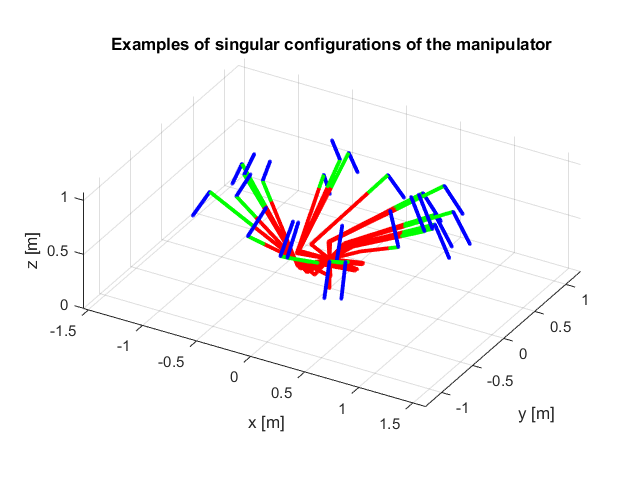

figure
for i = 1:numel(F_filtered)   
    plot_robot(SOL_plot(:,i),L,angle,gcf);
    hold on
end
grid on
axis equal
view(30,30)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Examples of singular configurations of the manipulator')
plot_kin_directory = ['C:\Users\miche\OneDrive - unibs.it\University\Magistrale - UNIBS\' ...
                      '1_Primo Anno\Servosystems & Robotics\Servosystems & Robotics Project\src\WS & Robot Plotting\plots'];

set(gcf,'renderer','painters');
exportgraphics(gcf, strcat(plot_kin_directory,'\sing_config.pdf'))